# **Численные методы в СПб АУ РАН**

## **Задание по практике №1**

Кузьмичев Артём, 4 курс

## **№9 (упражнения к разделу 4.4)**

*Первая часть задания - упражение*

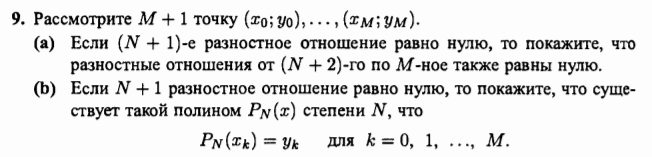

#### `Доказательство пункта (а):`

    Рассмотрим реккурентное правило построение разностных отношений высокого порядка:


$$f\left\lbrack x_{k-j} ,x_{k-j+1} ,\cdots ,x_k \right\rbrack =\frac{f\left\lbrack x_{k-j+1} ,\cdots ,x_k \right\rbrack -f\left\lbrack x_{k-j} ,\cdots ,x_{k-1} \right\rbrack }{x_k -x_{k-j} }$$


    Очевидно, что при подстановке в правую часть нулей следующее разностное отношение оказывается нулевым, таким образом, все разностные отношения от (N+2)-го до M-ого обращаются в нуль

#### `Доказательство пункта (б):`

    Применим теорему 4.5 о существовании интерполяционного полинома Ньютона к данным точкам. 

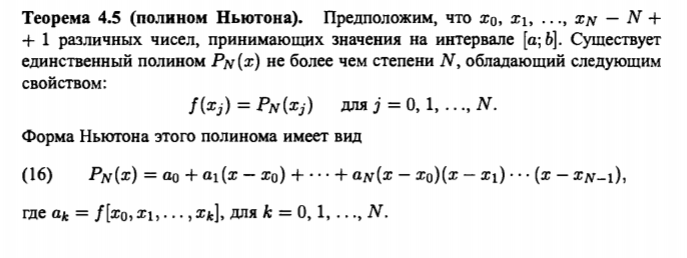

   Так как точек $M+1$, интерполяционный многочлен имеет степень не более чем $M$. Однако в формуле Ньютона (N+1)-й и все последующие коэффициенты обращаются в ноль по доказанному в пункте (а), так как они равны разностным отношениям:  


$$\forall \;k\ge N+1\;\left(a_k =f\left\lbrack x_0 ,\cdots ,x_k \right\rbrack =0\right)$$


Поэтому наибольшим членом с ненулевым коэффициентом оказывается член степени $N$, а значит, интерполяционный многочлен имеет степень не более $N$, что и требовалось доказать

## **№1 (алгоритмы и программы к разделу 4.4)**

*Вторая часть задания отсылает нас к предыдущему разделу пособия*

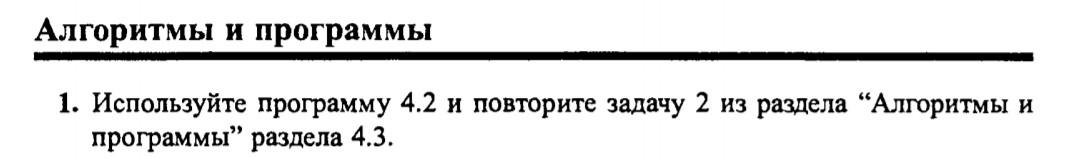

*На изображении ниже представлена задача 2 из раздела 4.3*

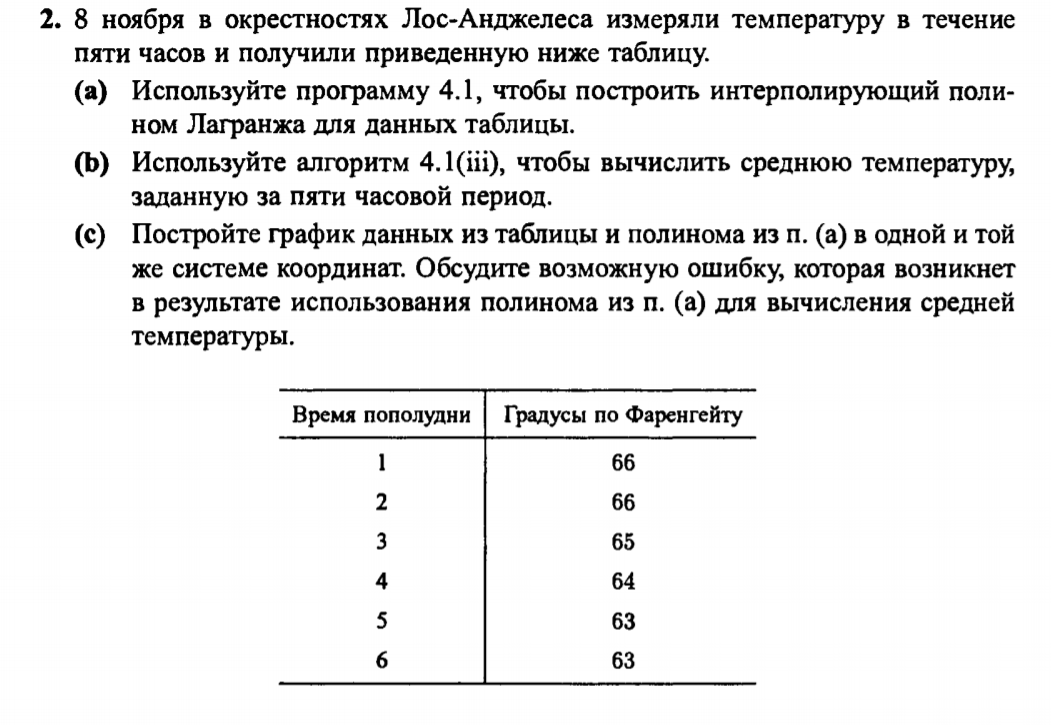

#### Пункт (а)

Зададим вектор абсцисс и вектор ординат точек в соответствии с таблицой

time = 1:6;
temperature = [66 66 65 64 63 63];

Получим коэффициенты интерполирующего полинома Ньютона с помощью функции newpoly (опредление в конце скрипта .mlx)

coeffs = newpoly(time, temperature);
poly2sym(coeffs) % Естественное представление многочлена

$$ans = \frac{x^{5}}{60}-\frac{7\,x^{4}}{24}+2\,x^{3}-\frac{161\,x^{2}}{24}+\frac{599\,x}{60}+61$$

#### Пункт (б)

Неопределённый интеграл от полинома - также полином. Его вычисление можно выполнить с помощью алгоритма искуственного деления 4.1(iii). Константу интегрирования положим равной нулю

n = length(coeffs);

int_constant = 0; 
intcoeffs(n+1) = int_constant;

for i = n:-1:1  
    intcoeffs(i) = coeffs(i)/(n-i+1); % делим коэффициент на значение степени, при которой тот стоит, увеличив её на 1
end
poly2sym(intcoeffs)

$$ans = \frac{x^{6}}{360}-\frac{7\,x^{5}}{120}+\frac{x^{4}}{2}-\frac{161\,x^{3}}{72}+\frac{599\,x^{2}}{120}+61\,x$$

Сравним результат со встроенной функцией polyint()

poly2sym(polyint(coeffs))

$$ans = \frac{x^{6}}{360}-\frac{7\,x^{5}}{120}+\frac{x^{4}}{2}-\frac{161\,x^{3}}{72}+\frac{599\,x^{2}}{120}+61\,x$$

Для вычисления определённого интеграла применим формулу Ньютона-Лейбница $\int_a^b f\left(x\right)=F\left(b\right)-F\left(a\right)$ , где первообразной выступает найденных выше многочлен с коэффициентами intcoeffs 

a = time(1);
b = time(end);

Int = polyval(intcoeffs,b) - polyval(intcoeffs,a);

 оценим среднюю температуру $\bar{t} =\frac{\int_a^b f\left(x\right)}{b-a}$

meanT = Int/(b-a)

meanT = 64.5000

#### Пункт (в)

Построим графики в одной системе координат:

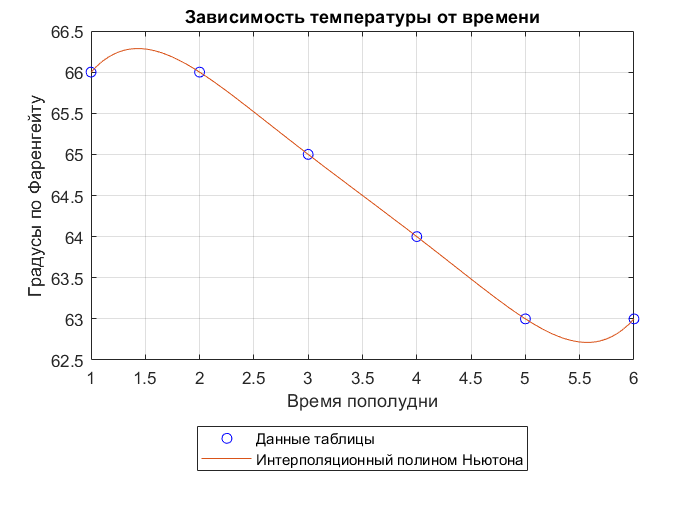


plot(time, temperature, "bo")
grid on
hold on
timeaxis = linspace(a,b,100);
plot(timeaxis, polyval(coeffs,timeaxis));

xlabel("Время пополудни");
ylabel("Градусы по Фаренгейту");
title("Зависимость температуры от времени");
legend(["Данные таблицы","Интерполяционный полином Ньютона"],"Location",'southoutside');

*Возможная ошибка при оценке средней температуры связана с несоответствием реальной зависимости температуры и поведения графика полинома в интервалах между измерениями *

## Приложение

#### Определение функции, осуществляющей построение интреполяционного полинома Ньютона

*Программа 4.2 пособия, стр.255 (с незначительными модификациями)*

function C = newpoly(X,Y)
%Вход   -   X - вектор абсциссfunction [C] = newpoly(X,Y)
%       -   Y - вектор ординат
%Выход  -   C - вектор коэффициентов интерполяционного полинома Ньютона
%       -   D - таблица разностных отношений

n=length(X);
D=zeros(n,n);
D(:,1)=Y;

% Вычсисление таблицы разностных отношений
for j=2:n
    for k=j:n
        D(k,j) =(D(k,j-1)-D(k-1,j-1))/(X(k)-X(k-j+1));
    end
end

% Вычсисление коэффициентов интерполяционного полинома Ньютона
C = D(n,n);
for k=(n-1):-1:1
    C = conv (C,poly(X(k)));
    m = length(C);
    C(m) = C(m) + D(k,k);
end

end